# S1: - Stability analysis depending on k

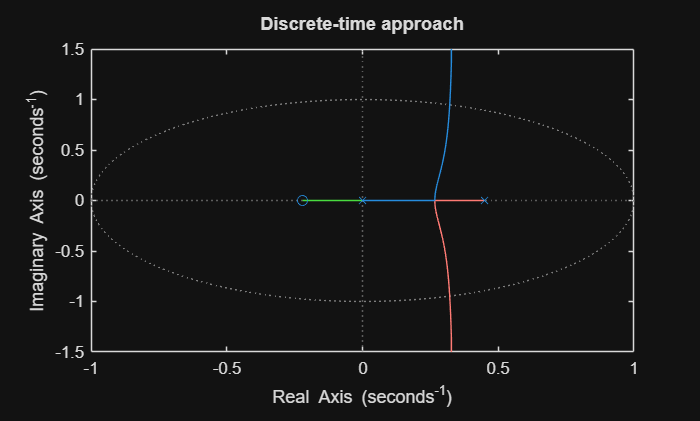

clear; % erase all the existing workspace variables
num = [240]; den = [1 40]; % the nominator and denominator of the process
Hp = tf(num,den, 'iodelay', 0.025); % the process transfer function
T = 0.02; % the sampling period
Hdes = c2d(Hp, T, 'zoh'); % the open loop discrete time transfer function
% subplot(121); rlocus(Hp); title('Continuous-time approach'); % we cannot
% plot rlocus for H with delay
rlocus(Hdes)
title('Discrete-time approach')

zpk(Hdes) % tf - products of zeros and poles


ans =
 
           2.7071 (z+0.2205)
  z^(-2) * -----------------
              (z-0.4493)
 
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.


clc
k = 0:1e-3:0.318;
p = rlocus(Hdes, k)

p =    0.0000 + 0.0000i  -0.0325 + 0.0000i  -0.0440 + 0.0000i  -0.0522 + 0.0000i  -0.0587 + 0.0000i  -0.0642 + 0.0000i  -0.0689 + 0.0000i  -0.0731 + 0.0000i  -0.0769 + 0.0000i  -0.0803 + 0.0000i  -0.0834 + 0.0000i  -0.0864 + 0.0000i  -0.0891 + 0.0000i  -0.0916 + 0.0000i  -0.0940 + 0.0000i  -0.0962 + 0.0000i  -0.0983 + 0.0000i  -0.1003 + 0.0000i  -0.1022 + 0.0000i  -0.1040 + 0.0000i  -0.1058 + 0.0000i  -0.1074 + 0.0000i  -0.1090 + 0.0000i  -0.1106 + 0.0000i  -0.1120 + 0.0000i  -0.1135 + 0.0000i  -0.1148 + 0.0000i  -0.1161 + 0.0000i  -0.1174 + 0.0000i  -0.1186 + 0.0000i  -0.1198 + 0.0000i  -0.1210 + 0.0000i  -0.1221 + 0.0000i  -0.1232 + 0.0000i  -0.1243 + 0.0000i  -0.1253 + 0.0000i  -0.1263 + 0.0000i  -0.1273 + 0.0000i  -0.1282 + 0.0000i  -0.1291 + 0.0000i  -0.1300 + 0.0000i  -0.1309 + 0.0000i  -0.1318 + 0.0000i  -0.1326 + 0.0000i  -0.1334 + 0.0000i  -0.1342 + 0.0000i  -0.1350 + 0.0000i  -0.1358 + 0.0000i  -0.1365 + 0.0000i  -0.1372 + 0.0000i
   0.0000 + 0.0000i   0.0417 + 0.0000i   0.06

[k', p']

ans =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.4493 + 0.0000i
   0.0010 + 0.0000i  -0.0325 + 0.0000i   0.0417 + 0.0000i   0.4401 + 0.0000i
   0.0020 + 0.0000i  -0.0440 + 0.0000i   0.0630 + 0.0000i   0.4303 + 0.0000i
   0.0030 + 0.0000i  -0.0522 + 0.0000i   0.0817 + 0.0000i   0.4198 + 0.0000i
   0.0040 + 0.0000i  -0.0587 + 0.0000i   0.0995 + 0.0000i   0.4085 + 0.0000i
   0.0050 + 0.0000i  -0.0642 + 0.0000i   0.1174 + 0.0000i   0.3961 + 0.0000i
   0.0060 + 0.0000i  -0.0689 + 0.0000i   0.1359 + 0.0000i   0.3823 + 0.0000i
   0.0070 + 0.0000i  -0.0731 + 0.0000i   0.1559 + 0.0000i   0.3665 + 0.0000i
   0.0080 + 0.0000i  -0.0769 + 0.0000i   0.1788 + 0.0000i   0.3474 + 0.0000i
   0.0090 + 0.0000i  -0.0803 + 0.0000i   0.2080 + 0.0000i   0.3217 + 0.0000i
   0.0100 + 0.0000i  -0.0834 + 0.0000i   0.2664 - 0.0238i   0.2664 + 0.0238i
   0.0110 + 0.0000i  -0.0864 + 0.0000i   0.2678 - 0.0656i   0.2678 + 0.0656i
   0.0120 + 0.0000i  -0.0891 + 0.0000i   0.2692 - 0.0893i   0.2692 + 0

## Overdamped case, k = (0, 0.00986);

k = 0.005;
Ho = feedback(k*Hdes, 1);

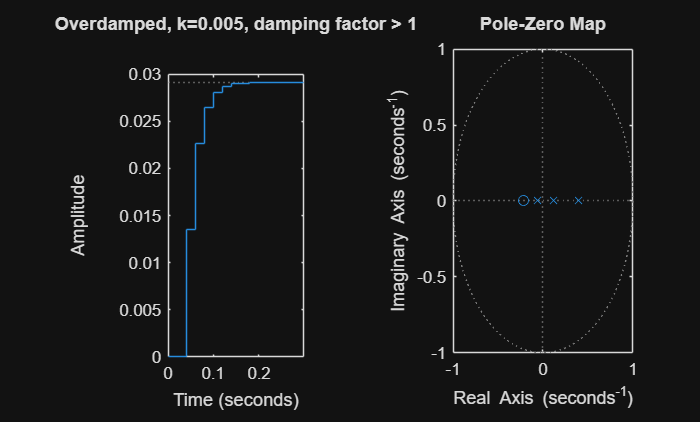

figure,
subplot(121); step(Ho, 0.3); title('Overdamped, k=0.005, damping factor > 1')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - in the unity circle (3 real poles) (-0.0642, 0.117, 0.396)

## Critically damped case, k = 0.00986;

k = 0.00986;
Ho = feedback(k*Hdes, 1);

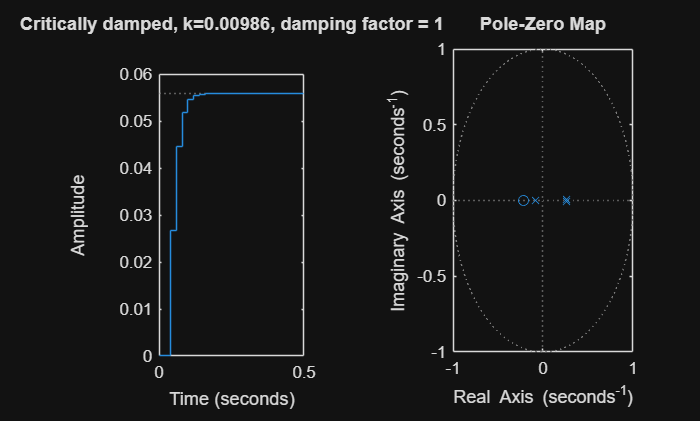

figure,
subplot(121); step(Ho, 0.5); title('Critically damped, k=0.00986, damping factor = 1')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - in the unity circle (2 equal real poles and one going to zero)
%                              - (+0.266)

## Underdamped case, k = (0.00986, 0.318);

k = 0.2;
Ho = feedback(k*Hdes, 1);

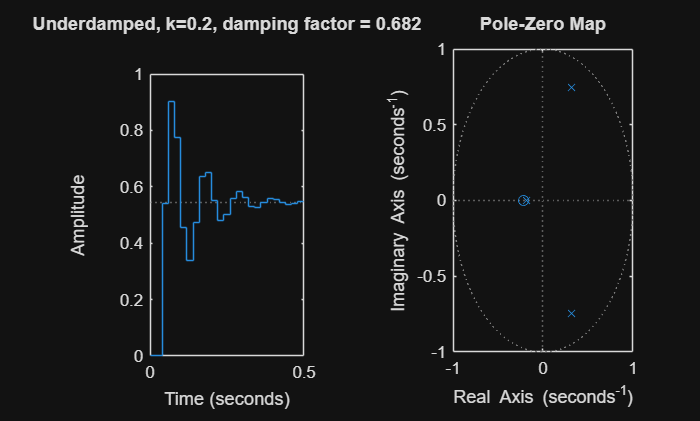

figure,
subplot(121); step(Ho, 0.5); title('Underdamped, k=0.2, damping factor = 0.177')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - in the unity circle
%                              - 2 complex conjugated poles (0.316 +- 0.746j)
%                              - one real pole going to zero

## Undamped case, k = 0.318;

k = 0.327;
Ho = feedback(k*Hdes, 1);

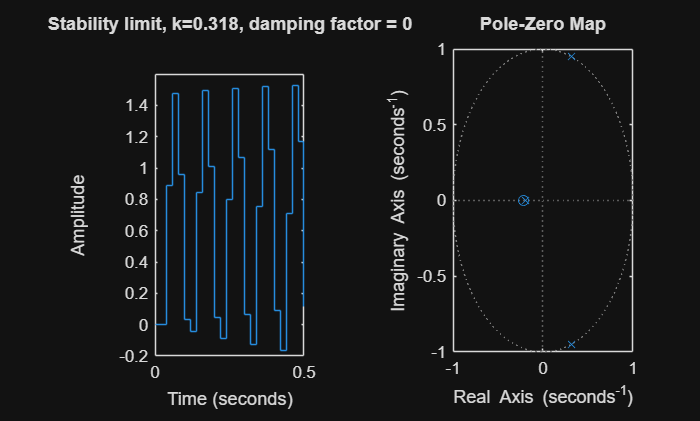

figure,
subplot(121); step(Ho, 0.5); title('Stability limit, k=0.318, damping factor = 0')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - exactly on the unity circle (0.321 +- 0.939j)

## Unstable case, k = (0.318, +inf);

k = 5;
Ho = feedback(k*Hdes, 1);

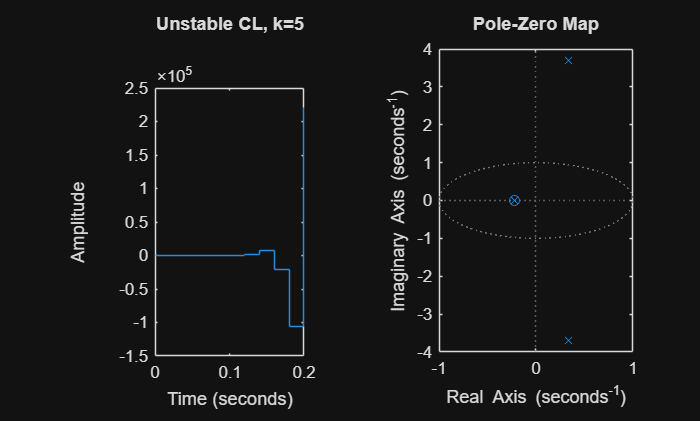

figure,
subplot(121); step(Ho, 0.2); title('Unstable CL, k=5')
subplot(122); Ho = feedback(k*Hdes, 1); pzmap(Ho)


% where the poles are located? - outside unity circle, unstable cl 
%                              - (0.334 +- 3.68j)